%1) Gmag_out: The frequency domain magnitude array after applying the Gaussian to the DFT of the input image. 
%2) Ixy: The image of 2 nd derivative values once in the x direction and once in the y direction ( the xy 2nd derivative ) of the image convolved with the Gaussian. 
%3) B: The bar strength image. 

sigma = .95

sigma = 0.9500


img = im2double(im2gray(imread("https://scontent-atl3-1.cdninstagram.com/v/t51.2885-15/319119476_1089005355127553_7690510107852126119_n.jpg?stp=dst-jpg_e35&_nc_ht=scontent-atl3-1.cdninstagram.com&_nc_cat=105&_nc_ohc=ChhQIfW3mmMAX_Ducoz&edm=ACWDqb8BAAAA&ccb=7-5&ig_cache_key=Mjk5MTM0MjU2NTA5MDUzNDY0OQ%3D%3D.2-ccb7-5&oh=00_AfC-yBQb1LzadRVh9ZAKNO_qBR8lTMxLOAeprez9KKBO-w&oe=63C5980F&_nc_sid=1527a3")));
img = sample128(img)

img =     0.8588    0.8549    0.8706    0.8588    0.8706    0.8667    0.8667    0.8784    0.8824    0.8941    0.8902    0.9059    0.9020    0.9098    0.9098    0.9176    0.9137    0.8863    0.8941    0.8902    0.8784    0.8745    0.8745    0.8627    0.8588    0.8667    0.8824    0.8627    0.8627    0.8667    0.8471    0.8510    0.8745    0.8784    0.8824    0.8784    0.8824    0.8667    0.8549    0.8588    0.8627    0.8549    0.8627    0.8667    0.8588    0.8667    0.8510    0.8549    0.8588    0.8549
    0.8627    0.8627    0.8667    0.8706    0.8745    0.8706    0.8667    0.8667    0.8706    0.8784    0.8784    0.8745    0.8941    0.8980    0.9020    0.8980    0.9059    0.9020    0.8941    0.8941    0.8863    0.8745    0.8784    0.8667    0.8588    0.8627    0.8706    0.8667    0.8627    0.8549    0.8471    0.8431    0.8471    0.8549    0.8706    0.8588    0.8588    0.8627    0.8549    0.8471    0.8588    0.8471    0.8431    0.8510    0.8549    0.8667    0.8588    0.8471    0.8392   


[mag, phase] = AmpPhaseDFT(img);
[fsize_y, fsize_x, ~] = size(mag)

fsize_y = 65

fsize_x = 128

mag

mag = 	1.0e+03 *

    7.9610    0.3957    0.2789    0.5152    0.2272    0.2342    0.4627    0.1511    0.1102    0.2473    0.1289    0.1897    0.1456    0.1771    0.1648    0.1004    0.2134    0.0192    0.0792    0.1770    0.1208    0.0731    0.0921    0.0911    0.0331    0.0367    0.0119    0.0834    0.0125    0.0589    0.0611    0.0807    0.0390    0.1082    0.1400    0.0234    0.0430    0.0394    0.0869    0.1209    0.0531    0.0824    0.0594    0.0741    0.0191    0.0252    0.0277    0.0320    0.0980    0.0319
    2.0290    0.4320    0.2681    0.2513    0.1494    0.1920    0.4012    0.7380    0.0595    0.0614    0.2753    0.2065    0.2104    0.0623    0.1079    0.1609    0.2110    0.0663    0.1472    0.0204    0.1504    0.0973    0.1348    0.0665    0.1513    0.0386    0.1719    0.0835    0.0923    0.0458    0.0286    0.0701    0.1309    0.1117    0.0684    0.0118    0.0665    0.1597    0.0500    0.0178    0.0724    0.0085    0.0094    0.0054    0.0613    0.0505    0.0761    0.0052 

phase

phase =          0   -0.0761   -0.1534   -2.7943    1.0655   -1.0055   -2.0887    1.4279   -1.8042    0.0649   -1.4366   -1.8084   -2.8959   -0.2460    1.2009   -1.9368   -1.8592    0.4814   -1.5380    2.8488    1.3650   -0.4776   -1.9844   -2.1786    0.5505   -0.8172    1.9122   -1.5191   -1.4622    0.1188   -2.8994   -2.1083    2.6384    1.1778   -1.2810    1.3191    1.7634    1.8814    1.4882   -3.0756    2.2402   -0.6228   -2.3318    2.2588    1.9774    1.0691    1.6234   -2.3336   -3.0141    3.1310
    0.4285   -0.8191   -1.9048   -0.4440   -2.0243   -2.0311    1.4053   -0.1254    0.5534    2.0590   -2.8974    1.1410    0.0686    1.0249   -1.6188   -1.9764    0.3238    2.4680    0.5865   -2.8504   -0.5661   -2.4420    0.7340    2.7330   -1.2138   -3.0677   -0.5261   -0.1124   -0.5243    0.9309    1.6462    2.8836   -0.5751   -0.4515   -2.7767    1.7222   -1.5369    0.8390   -3.0067    3.0546   -1.6564    0.7491   -2.0803   -2.6469   -0.1722   -1.6515    1.3176    2.5360   -2.3533 

Gmag_out=zeros(size(mag));


[mag, phase] = AmpPhaseDFT(img);
[fsize_y, fsize_x, ~] = size(mag);
Gmag_out=zeros(size(mag));


for y=1:65
    for x=1:65
        Gmag_out(y,x) = mag(y,x)*exp(-0.5*(2*pi*sigma)^2*(((y-1)/128)^2+((x-1)/128)^2));
    end
end
for y=1:65
    for x=66:128
        Gmag_out(y,x) = mag(y,x)*exp(-0.5*(2*pi*sigma)^2*(((y-1)/128)^2+((x-129)/128)^2));
    end
end



Ixy=zeros(size(mag));

Gmag_out(y,x);

for x=1:65
    Ixy(:,x) = Gmag_out(:,x).*(2*pi*(x-1)/128);
end

for x=66:128
    Ixy(:,x) = Gmag_out(:,x).*(2*pi*(x-129)/128);
end

for y=1:65
    Ixy(y,:) = Ixy(y,:).*(-2*pi*(y-1)/128);
end



Ixy

Ixy =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -1.0388   -1.2852   -1.7967   -1.4138   -2.2488   -5.5716  -11.7889   -1.0685   -1.2188   -5.9437   -4.7931   -5.1955   -1.6218   -2.9392   -4.5496   -6.1520   -1.9811   -4.4830   -0.6285   -4.6865   -3.0442   -4.2184   -2.0720   -4.6716   -1.1779   -5.1568   -2.4563   -2.6511   -1.2812   -0.7759   -1.8398   -3.3113   -2.7154   -1.5930   -0.2617   -1.4089   -3.2110   -0.9514   -0.3195   -1.2236   -0.1354   -0.1391   -0.0753   -0.7913   -0.6047   -0.8445   -0.0537   -0.7390   

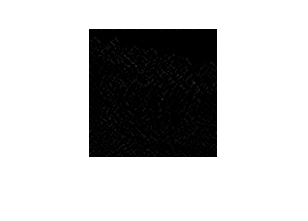

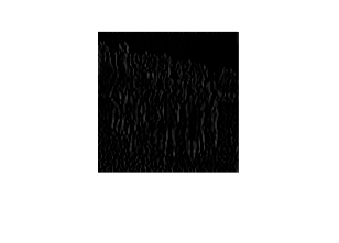



Ixx = zeros(size(mag));
for x=1:65
    Ixx(:,x) = Gmag_out(:,x)*-1*(2*pi*((x-1)/128))^2;  
end
for x=66:128
    Ixx(:,x) = Gmag_out(:,x)*-1*(2*pi*((x-129)/128))^2;  
end


Iyy = zeros(size(mag));

for y=1:65
    Iyy(y,:) = Gmag_out(y,:).*-1*(2*pi*((y-1)/128))^2;  
end



Ixy = ReconfromAmpPhase(Ixy,phase);
Ixx = ReconfromAmpPhase(Ixx,phase);
Iyy = ReconfromAmpPhase(Iyy,phase);
rGmag_out = ReconfromAmpPhase(Gmag_out,phase);

B = zeros(128);
evectors = zeros(128);

for x = 1:128
    for y = 1:128
        hessian = [Ixx(y,x), Ixy(y,x); Ixy(y,x), Iyy(y,x)];
        [evectors, evalues] = eig(hessian);
        if evalues(1,1) >= 0 || evalues(2,2) >= 0 %dark on light
            B(y,x) = max(evalues(1,1), evalues(2,2));
        end
    end
end

imshow(Ixy)

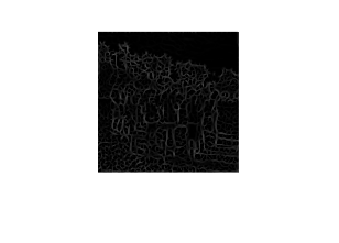

imshow(B)

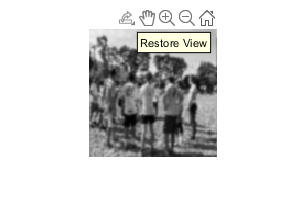

imshow(rGmag_out)